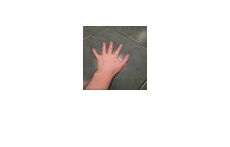

clear all;
close all; 

% Wczytanie zdjęcia z pliku (64 x 64 px)

img = imread('reka.ppm');

imshow(img)


M = [0.299 0.587 0.114;
    -0.168736 -0.331264 0.5;
    0.5 -0.418688 -0.081312];

A = [0;
    128;
    128];

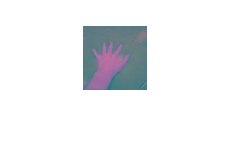

[ht, wt, ~] = size(img); % Wysokość, szerokość, warstwy
img = double(img);


% RGB na YCbCr
for h = 1:ht
    for w = 1:wt
            R = img(h, w, 1);
            G = img(h, w, 2);
            B = img(h, w, 3);

            RGB = [R;
                   G;
                   B];

            YCbCr = M * RGB + A;

            Y(h,w) = uint8(YCbCr(1));
            Cb(h,w) = uint8(YCbCr(2));
            Cr(h,w) = uint8(YCbCr(3));

    end
end


reka_ycc = cat(3, Y, Cb, Cr);
imshow(reka_ycc);

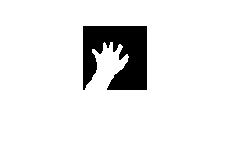

% Binaryzacja - segmentacja obszaru koloru skóry

Ta = 100;
Tb = 140;
Tc = 145;
Td = 180;

for h = 1:ht
    for w = 1:wt
        if(Ta < Cb(h,w) && Cb(h,w) < Tb && Tc < Cr(h,w) && Cr(h,w) < Td)
            maska(h,w) = 1;
        else
            maska(h,w) = 0;
        end
    end
end

imshow(maska);

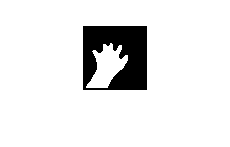

% Filtracja maski
x = medfilt2(maska, [5,5]);
x(1:2,:)=0; x(63:64,:)=0; x(:,1:2)=0; x(:,63:64)=0;
imshow(x)

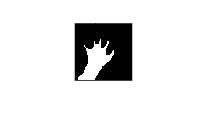

alk = imread('test.ppm');
imshow(alk)
A1 = bwmorph(maska, 'dilate');
A2 = bwmorph(maska, 'erode');
imshow(A2)

H = fspecial('gaussian',[3 3])

H =     0.0113    0.0838    0.0113
    0.0838    0.6193    0.0838
    0.0113    0.0838    0.0113


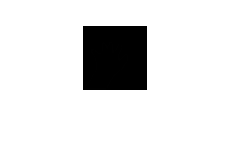

f = alk(:,:,1)/255;
X = uint8(x);
imshow(imabsdiff(f,X));

imwrite(x,'reka_po.ppm');

% Wyznaczenie środka ciężkości

N = ht;
M = wt;

m00 = 0;
m10 = 0;
m01 = 0;

for i = 0:N-1
    for j = 0:M-1
        m00 = m00 + x(i+1, j+1);
        m10 = m10 + (i * x(i+1, j+1));
        m01 = m01 + (j * x(i+1, j+1));
    end
end

m00

m00 = 1018

m10

m10 = 40656

m01

m01 = 24025

x_sc = m10/m00

x_sc = 39.9371

y_sc = m01/m00

y_sc = 23.6002

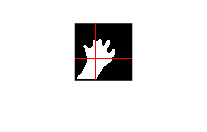


hold on
imshow(x);
line([1, M], [x_sc, x_sc], 'color', 'r');
line([y_sc, y_sc], [1, N], 'color', 'r');